tb = readmatrix('output.txt')

tb =          0         0    0.0011    0.1788
    1.0000         0    0.0011    0.1788
    2.0000         0    0.0011    0.1788
    3.0000         0    0.0011    0.1788
    4.0000         0    0.0011    0.1788
    5.0000         0    0.0011    0.1788
    6.0000         0    0.0011    0.1788
    7.0000         0    0.0011    0.1788
    8.0000         0    0.0011    0.1788
    9.0000         0    0.0011    0.1788


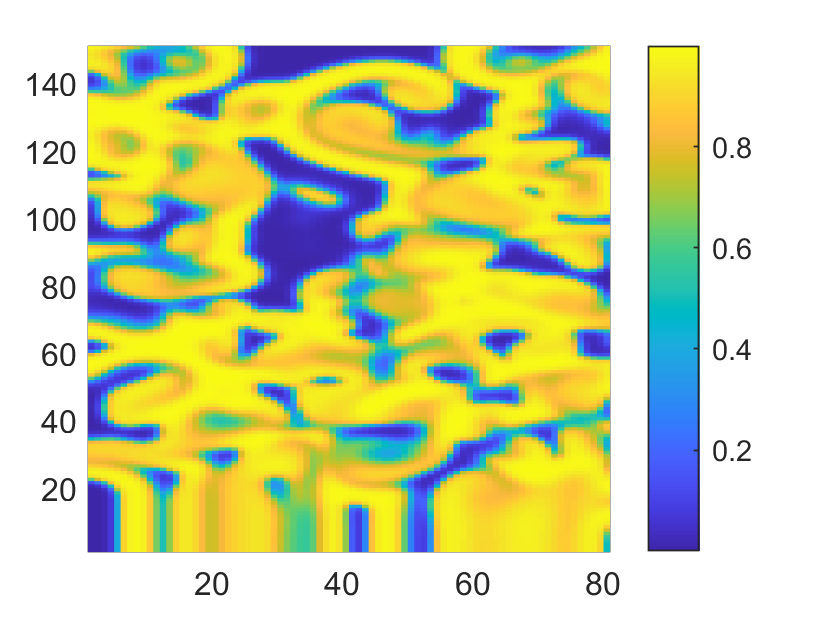

fname2 = '4';
Nx = 151;
x = tb(:,1);
y = tb(:,2);
u = tb(:,3);
v = tb(:,4);

u_mod = reshape(u,Nx,[]);
v_mod = reshape(v,Nx,[]);
fig = figure;
h = pcolor(u_mod);
set(h, 'EdgeColor', 'none');
colorbar
saveas(fig, ['test' fname2 '_U.png']);

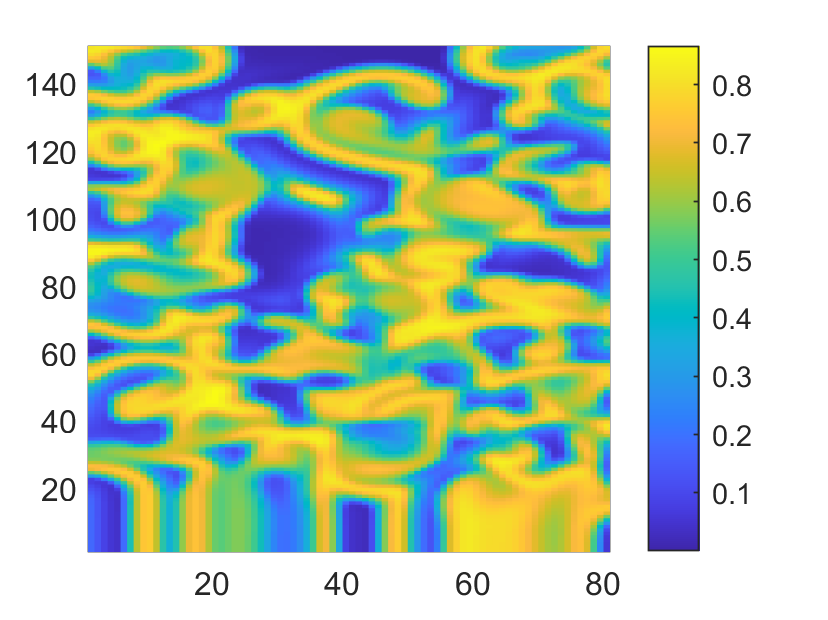


fig2 = figure;
h = pcolor(v_mod);
set(h, 'EdgeColor', 'none');
colorbar
saveas(fig2, ['test' fname2 '_V.png']);

laptop_threads = [1,2,4,8,12];
laptop_test2_time_omp = [127.760, 87.20, 74.607, 49.883, nan];
laptop_test2_time_mpi = [nan, 77.347, 63.243, 73.602, 92.048];

laptop_test4_time_omp = [24.584, 13.516, 11.150, 10.090, 63.914];
laptop_test4_time_mpi = [nan, 15.667, 11.512, 11.763, 11.884];

typhoon_threads = [1,2,4,8,12,16,20,24,32,40];
typhoon_test2_time_omp = [70.383, 36.481, 20.350, 12.341, 9.550, 8.788...
                          7.781, 7.135, 7.072, 8.098];
typhoon_test2_time_mpi = [nan, 60.763, 31.038, 18.029, 13.664, nan, 10.746...
                          9.988, nan, nan];

typhoon_test4_time_omp = [12.898, 6.919, 4.223, 3.091, 2.697, 2.584, 2.600...
                          2.422, 2.757, 3.406];
typhoon_test4_time_mpi = [nan, 11.195, 6.564, nan, nan, nan, nan, nan, nan, nan];


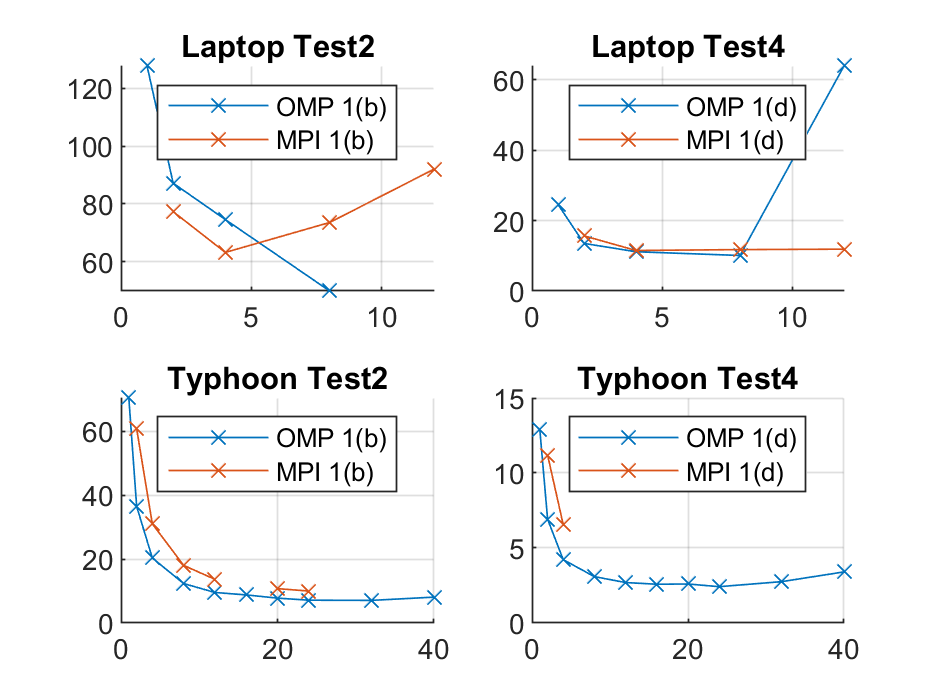

fig3 = figure;
subplot(2,2,1)
grid on
hold on
plot(laptop_threads, laptop_test2_time_omp, 'x-');
plot(laptop_threads, laptop_test2_time_mpi, 'x-');
legend(["OMP 1(b)", "MPI 1(b)"], 'location', 'best');
title("Laptop Test2");

subplot(2,2,2)
% fig4 = figure;
grid on
hold on
plot(laptop_threads, laptop_test4_time_omp, 'x-');
plot(laptop_threads, laptop_test4_time_mpi, 'x-');
legend(["OMP 1(d)", "MPI 1(d)"], 'location', 'best');
title("Laptop Test4");

subplot(2,2,3)
% fig5 = figure;
grid on
hold on
plot(typhoon_threads, typhoon_test2_time_omp, 'x-');
plot(typhoon_threads, typhoon_test2_time_mpi, 'x-');
legend(["OMP 1(b)", "MPI 1(b)"], 'location', 'best');
title("Typhoon Test2");

subplot(2,2,4)
% fig6 = figure;
grid on
hold on
plot(typhoon_threads, typhoon_test4_time_omp, 'x-');
plot(typhoon_threads, typhoon_test4_time_mpi, 'x-');
legend(["OMP 1(d)", "MPI 1(d)"], 'location', 'best');
title("Typhoon Test4");
saveas(fig3, "Performance_curves.png");